% Ultimate Bode Plot Analysis Script in MATLAB
eq3 = 10/s * ((1+s/0.1)*(1+s/1))/((1+s/5)*(1+s/20)^2)
f = expand(eq3)
h = simplify(f)
% Define transfer function numerator and denominator here
num = [500]; % Numerator coefficients (C(s))
den = [1 105 500 0]; % Denominator coefficients (R(s))

% Create transfer function
H = tf(num, den);

% Display the transfer function
fprintf('Transfer Function:\n');

Transfer Function:


display(H);

H =
 
           500
  ---------------------
  s^3 + 105 s^2 + 500 s
 
Continuous-time transfer function.
Model Properties



% Step 1: Find poles and zeros (and explain their significance)
[poles, zeros] = pzmap(H);

fprintf('Poles (The values of s where the denominator becomes zero, indicating system stability and dynamics):\n');

Poles (The values of s where the denominator becomes zero, indicating system stability and dynamics):


disp(poles);

     0
  -100
    -5




fprintf('Zeros (The values of s where the numerator becomes zero, indicating frequencies where output is nullified):\n');

Zeros (The values of s where the numerator becomes zero, indicating frequencies where output is nullified):


disp(zeros);

% Additional information about poles and their effects:
% - Poles in origo (s = 0): Magnitude falls by 20 dB/decade per pole, and phase starts at -90 degrees.
% - Poles outside origo: Affect magnitude and phase around their break frequency (abs(pole)).
% - Complex conjugate poles: Can cause resonance peaks and phase transitions.

% Step 2: Find break frequencies (frequencies where system behavior changes, typically at poles and zeros)
break_freq = abs(poles);
fprintf('Break frequencies (rad/s, critical points where magnitude/phase changes occur):\n');

Break frequencies (rad/s, critical points where magnitude/phase changes occur):


disp(break_freq);

     0
   100
     5




% Step 3: Calculate natural frequencies and damping ratios
wn = abs(poles); % Natural frequencies (magnitude of poles)
zeta = -real(poles) ./ wn; % Damping ratios (ratio of real to magnitude parts)

fprintf('Natural Frequencies (rad/s, oscillation frequency of poles):\n');

Natural Frequencies (rad/s, oscillation frequency of poles):


disp(wn);

     0
   100
     5




fprintf('Damping Ratios (dimensionless, indicates system response type: overdamped, underdamped, etc.):\n');

Damping Ratios (dimensionless, indicates system response type: overdamped, underdamped, etc.):


disp(zeta);

   NaN
     1
     1



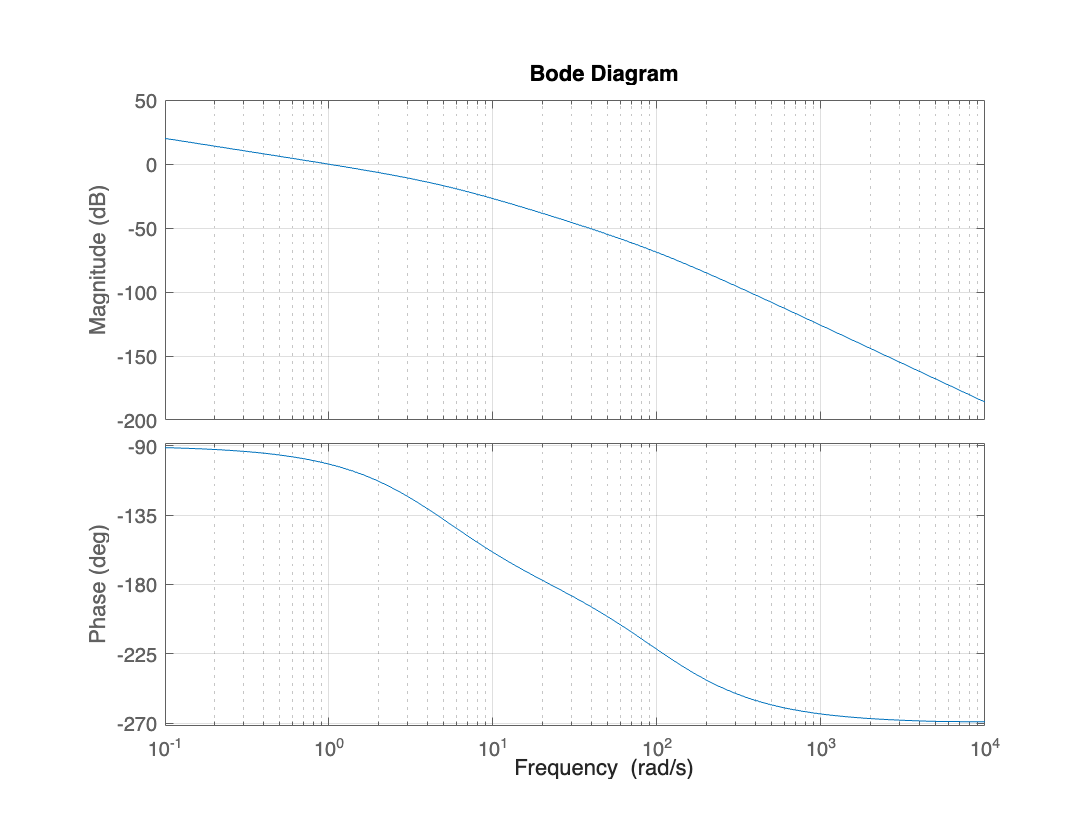


% Explanation of damping ratios:
% - zeta > 1: Overdamped system (no oscillations).
% - zeta = 1: Critically damped system (fastest non-oscillatory response).
% - 0 < zeta < 1: Underdamped system (oscillatory response).
% - zeta <= 0: Unstable system.

% Step 4: Bode plot (magnitude and phase)
figure;
bode(H);
grid on;
title('Bode Diagram');

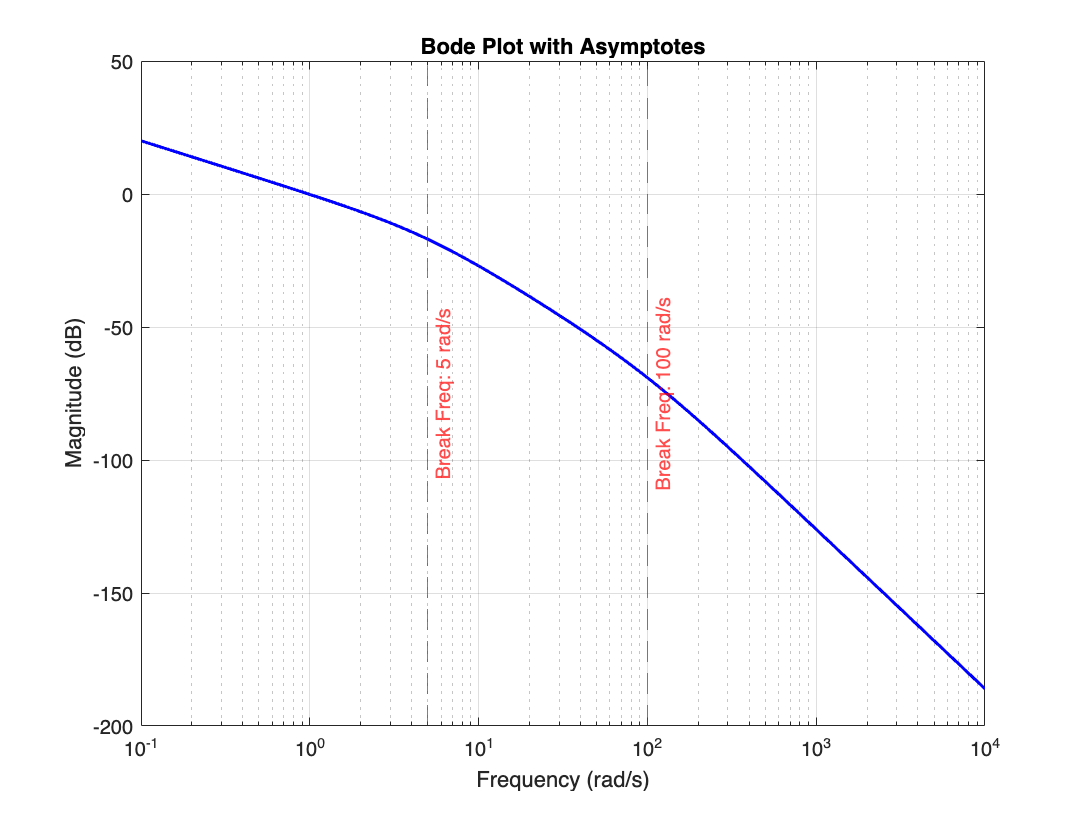


% Step 5: Bode plot with asymptotes (approximation of behavior)
figure;
[magnitude, phase, omega] = bode(H);
mag_dB = 20*log10(squeeze(magnitude));
phase_deg = squeeze(phase);
semilogx(omega, mag_dB, 'b', 'LineWidth', 1.5); % Actual magnitude plot
hold on;
% Add asymptotes manually based on break frequencies and system type
for i = 1:length(break_freq)
    xline(break_freq(i), '--r', ['Break Freq: ', num2str(break_freq(i)), ' rad/s'], 'LabelVerticalAlignment', 'middle');
end
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Bode Plot with Asymptotes');
grid on;
hold off;


% Step 6: Gain and phase margins
[GM, PM, Wcg, Wcp] = margin(H);

fprintf('Gain Margin (dB, the amount of gain increase possible before instability): %.2f\n', 20*log10(GM));

Gain Margin (dB, the amount of gain increase possible before instability): 40.42


fprintf('Phase Margin (deg, the additional phase lag possible before instability): %.2f\n', PM);

Phase Margin (deg, the additional phase lag possible before instability): 78.33


fprintf('Gain Crossover Frequency (rad/s, frequency where magnitude is 0 dB): %.2f\n', Wcg);

Gain Crossover Frequency (rad/s, frequency where magnitude is 0 dB): 22.36


fprintf('Phase Crossover Frequency (rad/s, frequency where phase is -180 degrees): %.2f\n', Wcp);

Phase Crossover Frequency (rad/s, frequency where phase is -180 degrees): 0.98


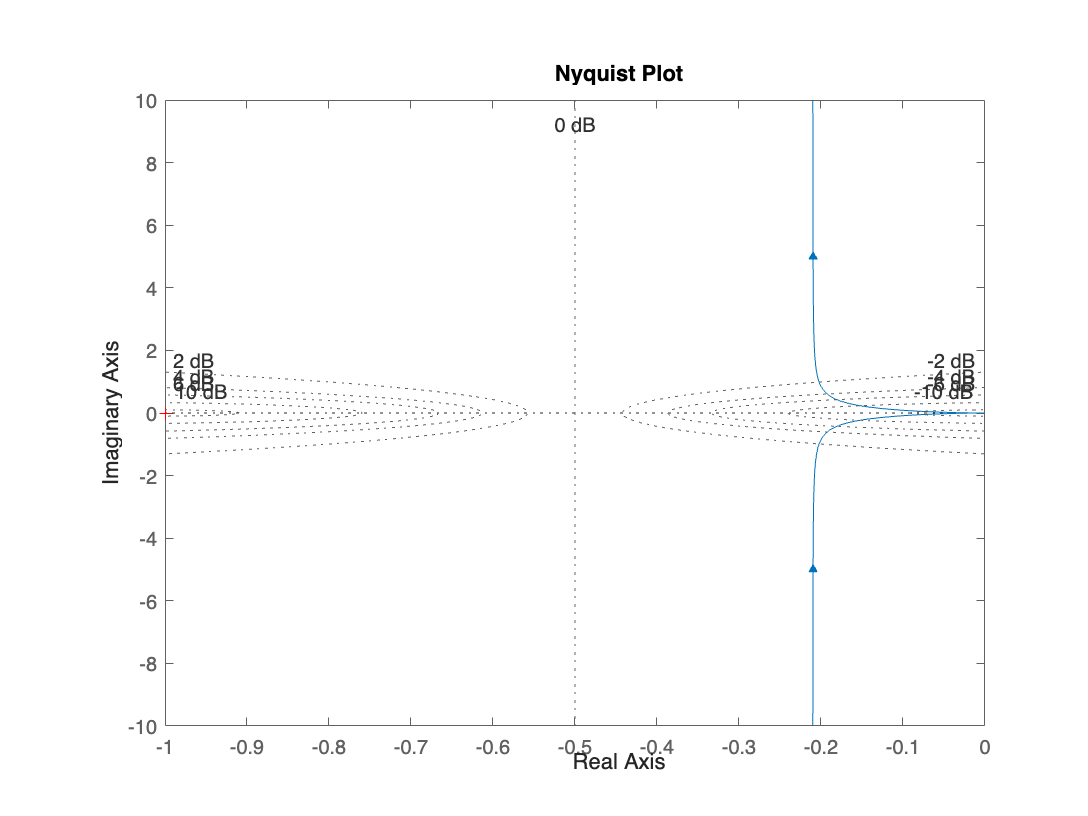


% Explanation of margins:
% - Gain Margin: How much gain can increase before the system becomes unstable.
% - Phase Margin: How much phase lag can increase before instability.
% - Gain Crossover Frequency: Frequency where magnitude is 0 dB.
% - Phase Crossover Frequency: Frequency where phase reaches -180 degrees.

% Step 7: Nyquist plot
figure;
nyquist(H);
grid on;
title('Nyquist Plot');


% Step 8: Step response
figure;
step(H);
grid on;
title('Step Response');

% Step 9: Additional details
% Compute DC gain if applicable
dc_gain = dcgain(H);
if isfinite(dc_gain)
    fprintf('DC Gain (steady-state gain at zero frequency): %.2f\n', dc_gain);
else
    fprintf('DC Gain: Infinite (System has a pole at the origin, indicating integration behavior)\n');
end

DC Gain: Infinite (System has a pole at the origin, indicating integration behavior)



% Display additional system characteristics
fprintf('System Characteristics:\n');

System Characteristics:


for i = 1:length(poles)
    fprintf('Pole %d:\n', i);
    fprintf('  Natural Frequency (wn): %.2f rad/s\n', wn(i));
    fprintf('  Damping Ratio (zeta): %.2f\n', zeta(i));
    if zeta(i) > 1
        fprintf('  System Type: Overdamped\n');
    elseif zeta(i) == 1
        fprintf('  System Type: Critically Damped\n');
    elseif zeta(i) > 0 && zeta(i) < 1
        fprintf('  System Type: Underdamped\n');
    else
        fprintf('  System Type: Unstable\n');
    end
end

Pole 1:


  Natural Frequency (wn): 0.00 rad/s


  Damping Ratio (zeta): NaN


  System Type: Unstable


Pole 2:


  Natural Frequency (wn): 100.00 rad/s


  Damping Ratio (zeta): 1.00


  System Type: Critically Damped


Pole 3:


  Natural Frequency (wn): 5.00 rad/s


  Damping Ratio (zeta): 1.00


  System Type: Critically Damped


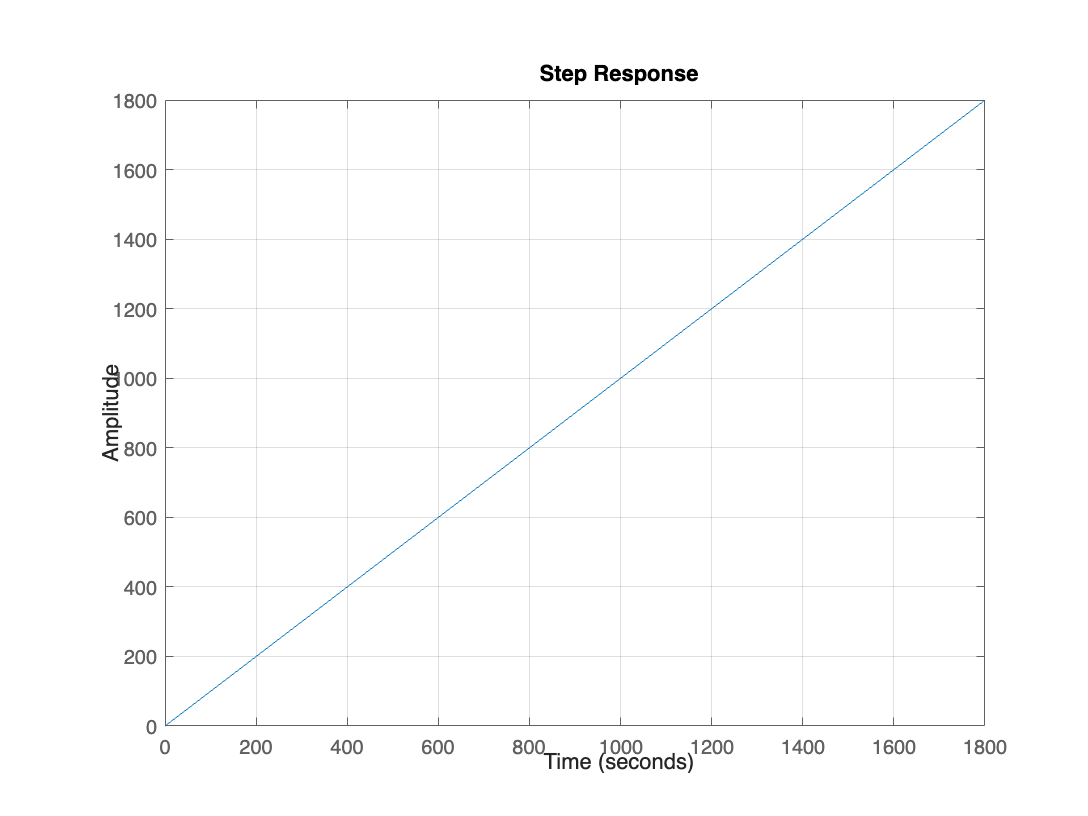


% Save results to a file
saveas(gcf, 'BodeDiagram_Asymptotes.png');

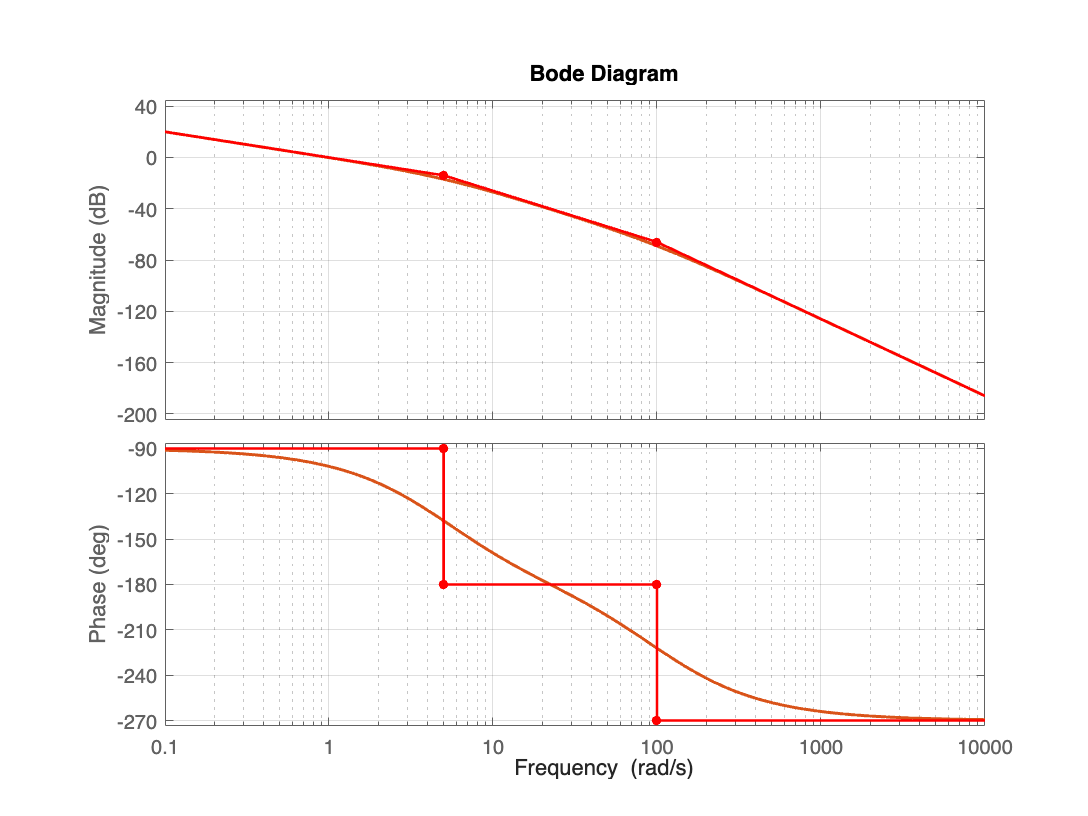



asymp(H)